# Foundations of Image Systems Engineering

### Chapter 1, Light Fields

Render the chess set scene with a pinhole camera (perspective) mode. We use a range of aperture sizes to show the blurring effect.

**Requires**: ISET3d-tiny and remote rendering.

## Initialize ISET/ISET3d

ieInit;
if ~piDockerExists, piDockerConfig; end

## Load the chess scene

The default chess set scene has a fairly small horizontal field of view, (30 deg). Thus there is little intensity fall off across the rendered scene.

thisR = piRecipeDefault('scene name','chessset');

## Increasing pinhole size

PBRT sets the pinhole radius (mm) of the perspective camera.

radius = [0,logspace(-3,-2,3)];
img = cell(4,1);
for ii=1:numel(radius)
    thisR.set('pinhole radius',radius(ii));
    scene = piWRS(thisR,'name',sprintf('Radius %.3f mm',radius(ii)),'verbosity',0,'show',false);
    scene = piAIdenoise(scene,'quiet',true);
    img{ii} = sceneGet(scene,'srgb');
end

## The image 

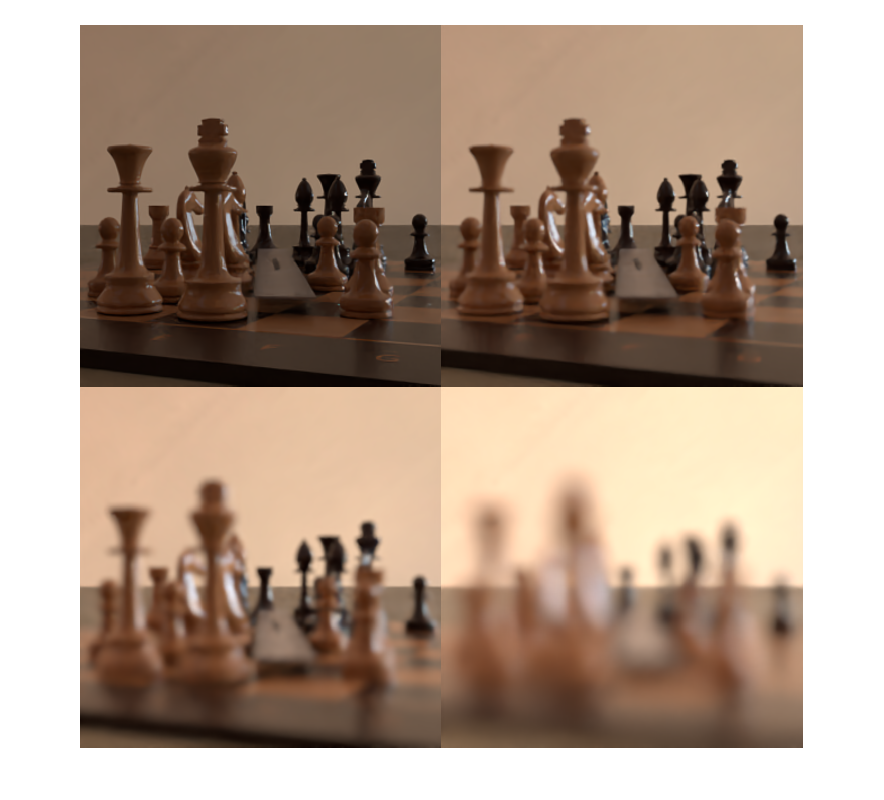

ieNewGraphWin; 
montage(img);

## End